clc;clear;
close all;

addpath(genpath('metrics'));
addpath(genpath('data'));

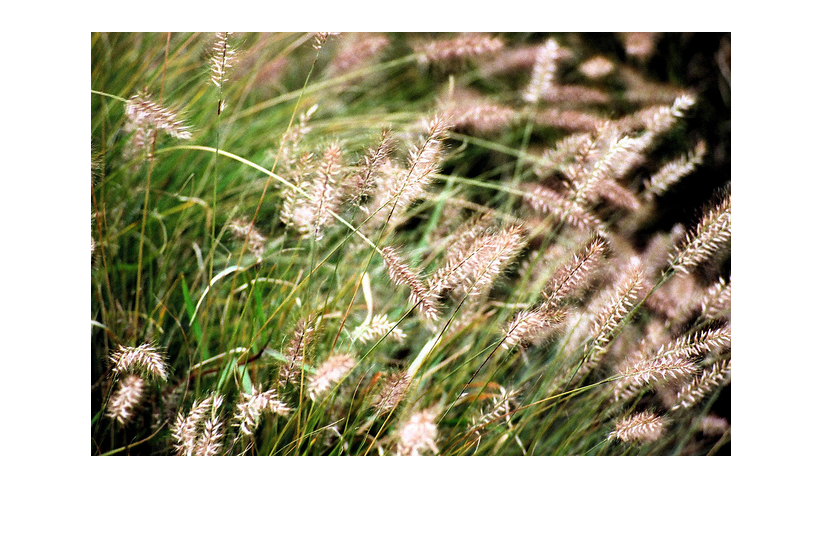

img = imread('out_of_focus0686.jpg');
figure, imshow(img);

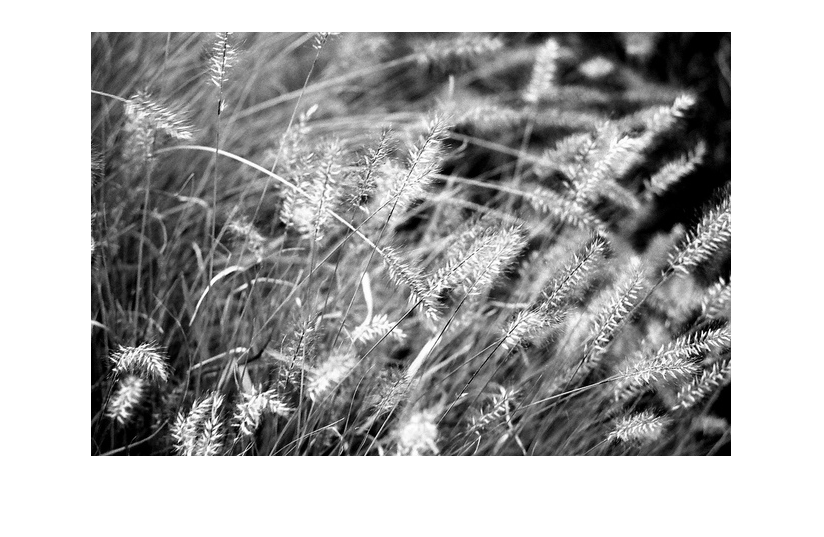

I=im2double(rgb2gray(img));
figure, imshow(I);

[height,width]=size(I);


interpOff = sqrt(2)/2;
P = padarray(I, [1 1], 'replicate');

% Entry (i,j) of this matrix contains the pixel to the
% right of (i,j) in I.
right = P(2:end-1, 3:end);
left = P(2:end-1, 1:end-2);
above = P(1:end-2, 2:end-1);
below = P(3:end, 2:end-1);
aboveRight = P(1:end-2, 3:end);
aboveLeft = P(1:end-2, 1:end-2);
belowRight = P(3:end, 3:end);
belowLeft = P(3:end, 1:end-2);